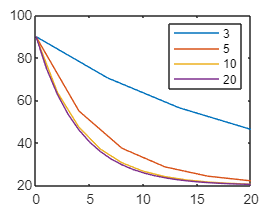

T0 = 90;
Ta = 20;
k = 0.25;

T = 20;

figure;

for N = [3, 5, 10, 20]
    [t, y] = IEMsolver(T0, T, N, k, Ta);
    plot(t, y);
    hold on;
end

legend(string([3, 5, 10, 20]));

xlabel("number of steps (N)");
ylabel("")

function [t, SOL] = IEMsolver(T0, T, N, k, Ta)
    dt = T/N;
    t = 0:dt:T;

    SOL = nan(1, length(t));
    SOL(1) = T0;

    for i = 2:length(t)
        zn = SOL(i-1);
        SL = -1*k*zn + k*Ta;
        SR = -1*k*(zn+dt*SL) + k*Ta;
        SOL(i) = zn + (dt/2)*(SL+SR);
    end
end